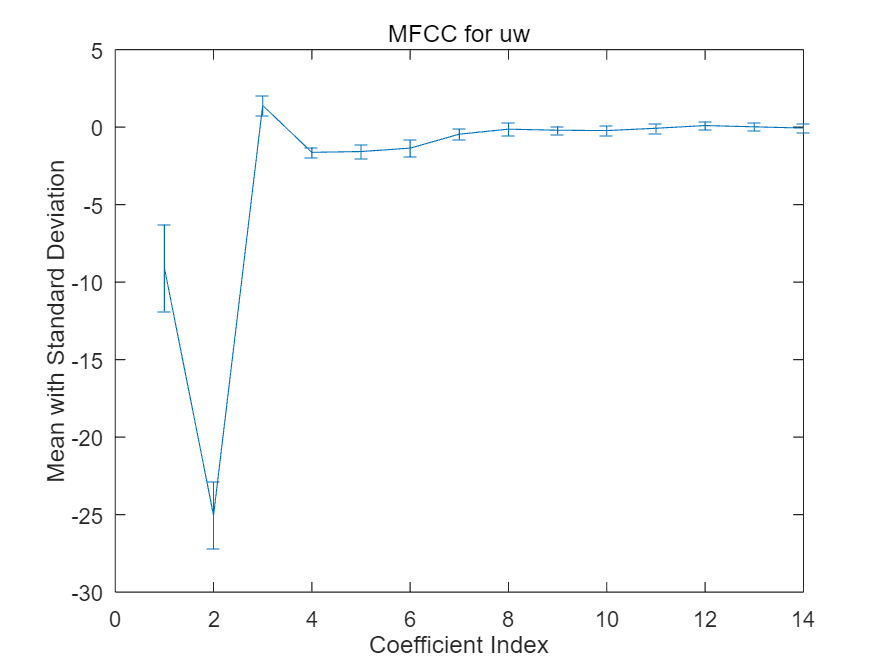

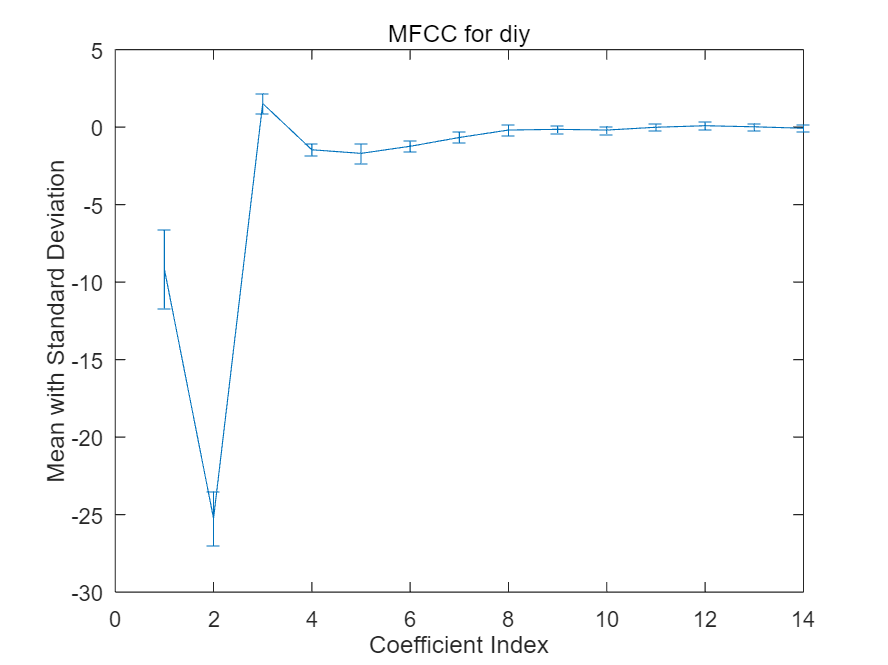

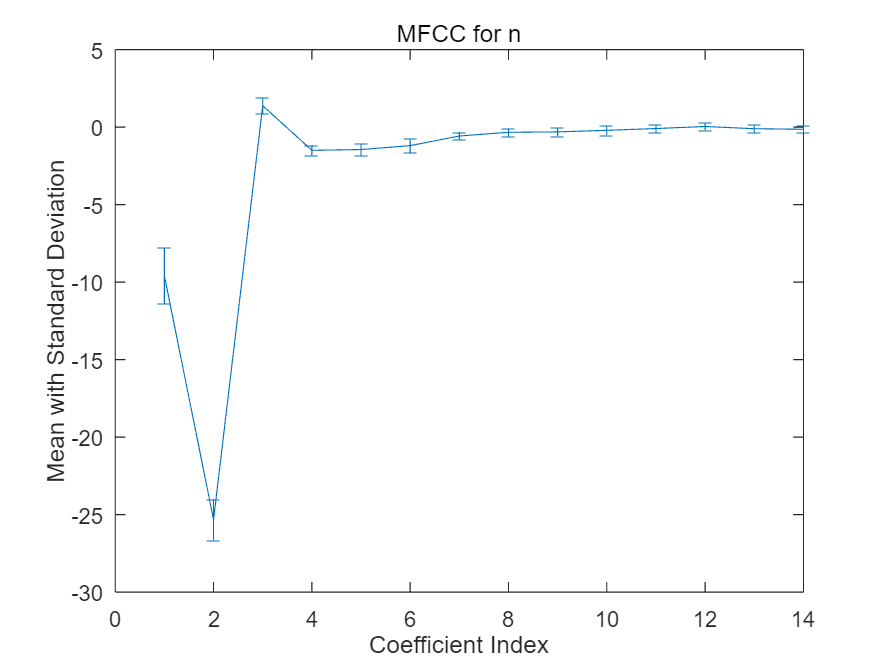

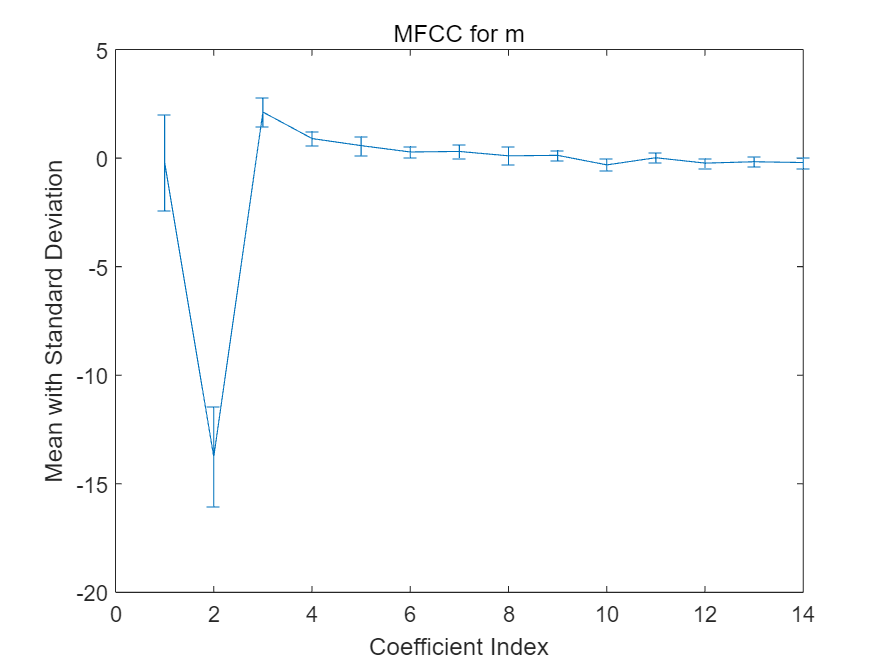

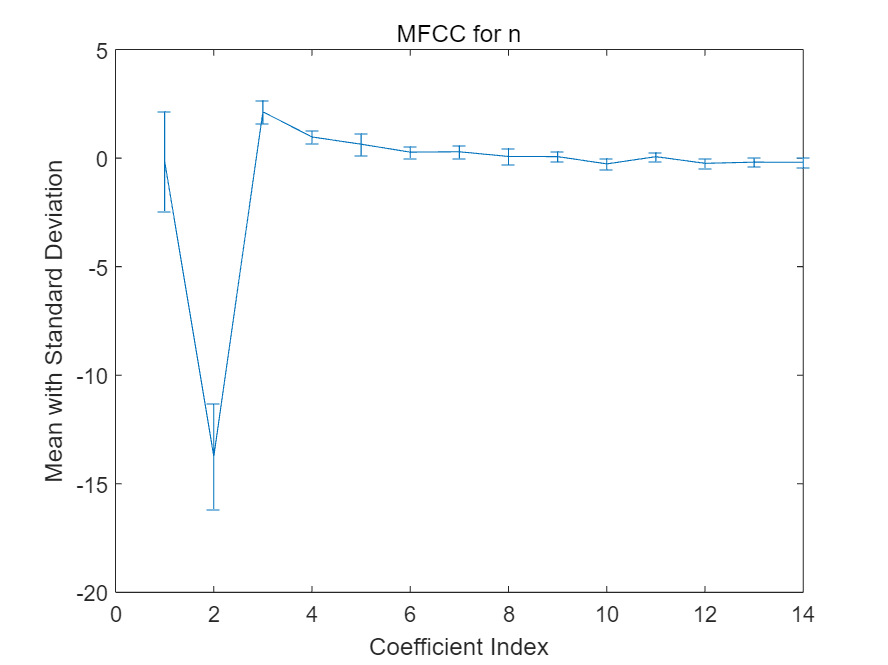

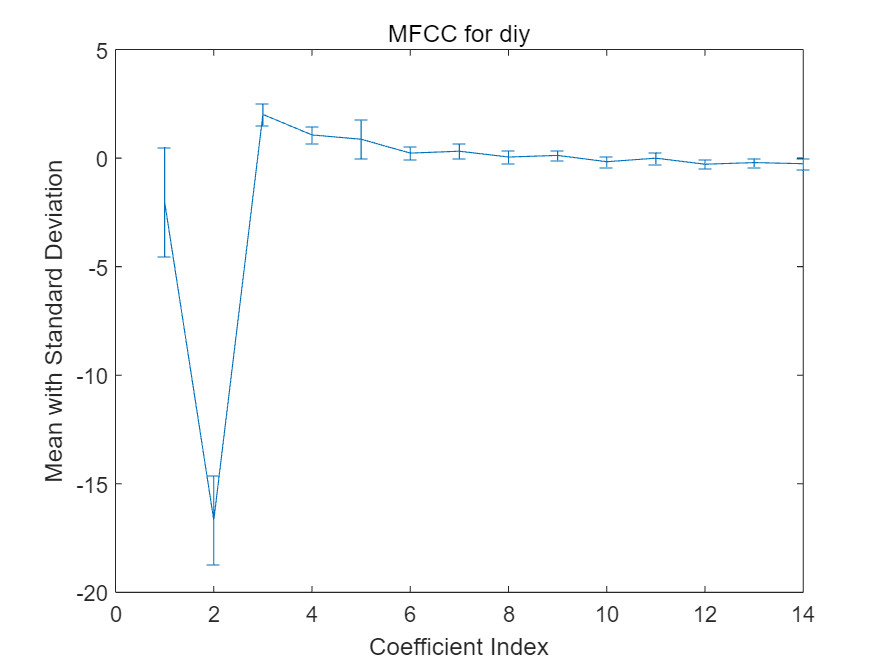

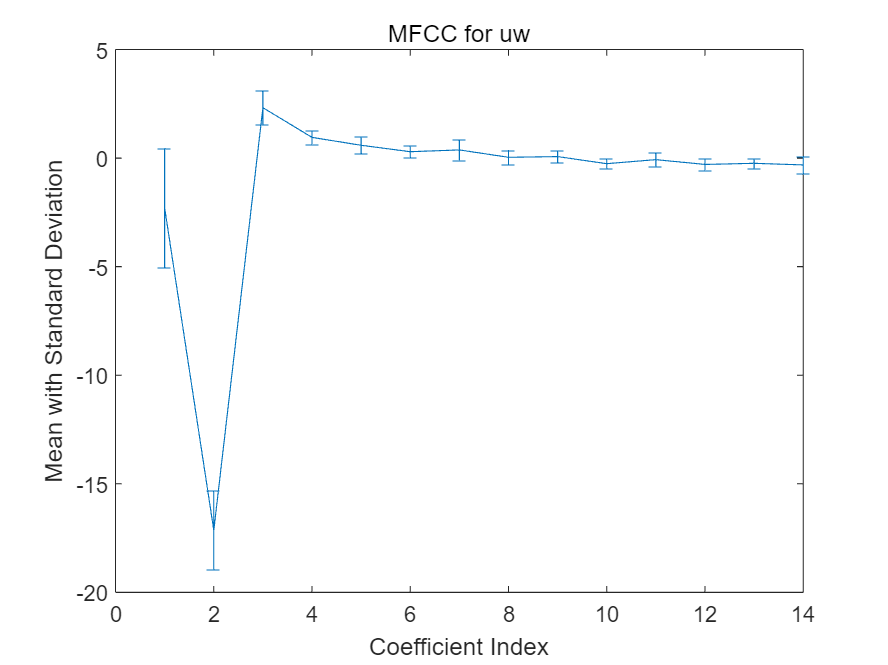

clear; close all; clc;

base_path = 'D:\W00Y0NG\PRGM2\MATLAB\2023mathFFT\MM18\kinect_data\';

% 각 음운별 파일 번호 리스트
phoneme_files = {
    'tiy', [0, 3, 5, 13, 17, 18, 23, 49, 58, 69, 76, 78],  
    'iy',  [1, 32, 40, 42, 44, 53, 57, 63, 67, 70, 74, 79],
    'piy', [2, 12, 19, 20, 25, 30, 33, 38, 39, 41, 68, 83],
    'm',   [4, 6, 10, 21, 24, 27, 28, 35, 36, 43, 54, 64],
    'n',   [7, 11, 15, 16, 22, 29, 37, 47, 55, 65, 72, 82],
    'diy', [8, 9, 14, 46, 48, 50, 52, 59, 62, 71, 73, 77],
    'uw',  [26, 31, 34, 45, 51, 56, 60, 61, 66, 75, 80, 81]
};
Fs = 16000; % 샘플링 레이트

for i = 1:size(phoneme_files, 1)
    phoneme = phoneme_files{i, 1};
    fileIndices = phoneme_files{i, 2};
    
    mfccResults = []; % MFCC 결과를 저장할 배열 초기화

    for j = 1:length(fileIndices)
        filename = fullfile(base_path, sprintf('%d.wav', fileIndices(j)));
        [y, Fs] = audioread(filename);
    
        y = y / max(abs(y));
        
        [coeffs, ~] = mfcc(y, Fs);
        mfccResults = [mfccResults; coeffs]; % 각 파일의 모든 MFCC 계수를 저장
    end
    
    % MFCC 결과의 변동성을 시각화 (표준편차 사용)
    mfccMean = mean(mfccResults, 1); % 계수별 평균
    mfccStd = std(mfccResults, 0, 1); % 계수별 표준편차

    figure;
    errorbar(mfccMean, mfccStd);
    title(['MFCC for ', phoneme]);
    xlabel('Coefficient Index');
    ylabel('Mean with Standard Deviation');
    
    % 결과를 파일로 저장
    saveFileName = sprintf('MFCC_result/MFCC_%s.mat', phoneme);
    save(fullfile(saveFileName), 'mfccResults');
end